# Slosh 3D, tilt about y axis 

Different parametrization of the pendulum

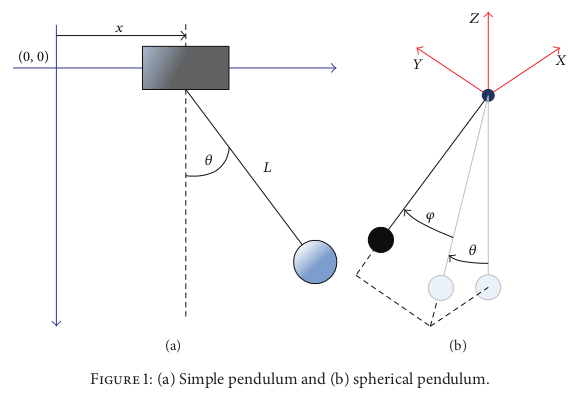

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the y axis of the container.

clc 
clear all

syms theta(t) psi(t) phi(t) beta(t) gamma(t)
syms t 
syms d h l m g M b cs
syms x(t) y(t) z(t)
sympref('AbbreviateOutput',false);

save_func = 0

save_func = 0

$\theta$ = angle between plane ZY and the mass, angle of the pendulum mapped in xz plane

$\phi$ = angle in the perpendicular direction, between the original pendulum and the mapped pendulum

$\psi$ =  rotation of the pendulum about its longitudinal axis z

$\beta$ = pitch rotation about the y axis of the container

$\gamma$ =  rotation about the x axis of the container

h = height of the container

d = distance from CoM to top of the liquid at rest (for full uniform liquid container it is h/2)

l = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container CoM with origin assumed to be at a distance d from the pivot

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to CoM

Derive the homogeneous transformation matrix from the world to the CoM reference frame (or CoR frame).

Define rotation matrix (rotation around y-axis followed by a rotation around x-axis)

% Rotation matrix about y-axis of angle beta
R_y_beta = [cos(beta),  0, sin(beta); 
             0,           1,           0; 
             -sin(beta),  0,  cos(beta)];
% R_y_beta=formula(R_y_beta)

R_x_gamma = [1,          0,          0; 
           0,   cos(gamma),  -sin(gamma); 
           0,   sin(gamma),  cos(gamma)];

R = R_y_beta*R_x_gamma

$$R(t) = \left(\begin{array}{ccc} \cos\left(\beta \left(t\right)\right) & \sin\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\\ 0 & \cos\left(\gamma \left(t\right)\right) & -\sin\left(\gamma \left(t\right)\right)\\ -\sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right) \end{array}\right)$$

% R = subs(R, [beta(t), gamma(t)], [beta(t), 0])

Define translation vector from inertial frame to CoR (CoM)

p = [x; y; z];
% p = [x;0;0];

Create homogeneous transformation matrix

T_wg = [R, p; 0 0 0 1];
T_wg = formula(T_wg);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to CoM:');

Homogeneous Transformation Matrix from world to CoM:


disp(T_wg);

$$\left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & \sin\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right) & x\left(t\right)\\ 0 & \cos\left(\gamma \left(t\right)\right) & -\sin\left(\gamma \left(t\right)\right) & y\left(t\right)\\ -\sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### CoM to pivot

Derive the homogeneous transformation matrix from the CoM reference frame to the pivot reference frame.

Define rotation matrices

% Rotation matrix about y-axis of angle -theta
R_y_theta = [cos(-theta),  0, sin(-theta); 
             0,           1,           0; 
             -sin(-theta),  0,  cos(-theta)];
R_y_theta = formula(R_y_theta)

$$R\_y\_theta = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & -\sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$


% Rotation matrix about x-axis of angle phi
R_x_phi = [1,          0,          0; 
           0,   cos(phi),  -sin(phi); 
           0,   sin(phi),  cos(phi)];
R_x_phi=formula(R_x_phi)

$$R\_x\_phi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


R_combined = R_y_theta * R_x_phi 

$$R\_combined = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (from the CoM reference frame)

p = [0; 0; d];

Create homogeneous transformation matrix

T_gp = [R_combined, p; 0 0 0 1];
T_gp = formula(T_gp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from liquid to pivot:');

Homogeneous Transformation Matrix from liquid to pivot:


disp(T_gp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pivot to Pendulum mass

R = eye(3)

R =      1     0     0
     0     1     0
     0     0     1


Define translation vector

p = [0; 0; -l];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wg*T_gp*T_pm

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\sin\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)-d\,\sin\left(\gamma \left(t\right)\right)+l\,\left(\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\left(\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right)$$

Explicitate the relative position of the pendulum mass with respect to its pivot

xr = l*cos(phi)*sin(theta);
yr = l*sin(phi);
zr = -l*cos(phi)*cos(theta);

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to $\theta$ and $\phi$.

### Kinetic Energy

Differentiate the pendulum mass coordinates

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(d\,\cos\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)-\frac{\partial }{\partial t}y\left(t\right)-l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)-l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;


### Potential energy

Derive the gravitational potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)+d\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right)+l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

Derive velocity of the relative pendulum mass

v2 = xr_dot^2 + yr_dot^2+ zr_dot^2;

D = b/2 *(v2);

D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L);

% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta);

% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

#### Theta

syms theta(t) phi(t) beta(t) gamma(t)
%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
% disp("Equation of motion with respect to theta:");
% disp(eqn_theta);
% disp("Latex Equation of motion with respect to theta:");
% disp(latex(eqn_theta));
eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
% disp(eqn1);

Substitute variables to the diff, sin and cos

syms c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma
syms theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(beta(t),t),t),diff(diff(gamma(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,phi_ddot,beta_ddot,gamma_ddot,x_ddot,y_ddot,z_ddot ]);

disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,beta_dot,gamma_dot])

$$eq\_sub3(t) = c_{\varphi }\,l\,\left(b\,c_{\varphi }\,l\,\dot{\theta }-c_{\theta }\,g\,m\,s_{\beta }+c_{\beta }\,c_{\theta }\,m\,\ddot{x}+c_{\varphi }\,l\,m\,\ddot{\theta }-c_{\theta }\,m\,s_{\beta }\,\ddot{z}-m\,s_{\gamma }\,s_{\theta }\,\ddot{y}-d\,{\dot{\gamma }}^{2}\,m\,s_{\theta }-{\dot{\beta }}^{2}\,{c_{\gamma }}^{2}\,d\,m\,s_{\theta }+\ddot{\beta }\,c_{\gamma }\,c_{\theta }\,d\,m-\ddot{\beta }\,c_{\gamma }\,c_{\varphi }\,l\,m+c_{\beta }\,c_{\gamma }\,g\,m\,s_{\theta }+c_{\beta }\,c_{\gamma }\,m\,s_{\theta }\,\ddot{z}+\ddot{\gamma }\,l\,m\,s_{\varphi }\,s_{\theta }+c_{\gamma }\,m\,s_{\beta }\,s_{\theta }\,\ddot{x}-2\,l\,m\,\dot{\varphi }\,s_{\varphi }\,\dot{\theta }-{\dot{\beta }}^{2}\,c_{\varphi }\,c_{\theta }\,l\,m\,s_{\theta }+c_{\varphi }\,c_{\theta }\,{\dot{\gamma }}^{2}\,l\,m\,s_{\theta }-2\,\dot{\beta }\,c_{\theta }\,d\,\dot{\gamma }\,m\,s_{\gamma }+2\,\dot{\beta }\,c_{\gamma }\,l\,m\,\dot{\varphi }\,s_{\varphi }+\ddot{\beta }\,c_{\theta }\,l\,m\,s_{\gamma }\,s_{\varphi }+2\,c_{\varphi }\,\dot{\gamma }\,l\,m\,\dot{\varphi }\,s_{\theta }+2\,\dot{\beta }\,c_{\gamma }\,c_{\theta }\,\dot{\gamma }\,l\,m\,s_{\varphi }+2\,\dot{\beta }\,c_{\varphi }\,c_{\theta }\,l\,m\,\dot{\varphi }\,s_{\gamma }+2\,\dot{\beta }\,c_{\varphi }\,{c_{\theta }}^{2}\,\dot{\gamma }\,l\,m\,s_{\gamma }-{\dot{\beta }}^{2}\,c_{\gamma }\,l\,m\,s_{\gamma }\,s_{\varphi }\,s_{\theta }+{\dot{\beta }}^{2}\,{c_{\gamma }}^{2}\,c_{\varphi }\,c_{\theta }\,l\,m\,s_{\theta }\right)$$

eq_sub = isolate(eq_sub3 == 0, theta_ddot)

$$eq\_sub = \ddot{\theta }=-\frac{b\,c_{\varphi }\,l\,\dot{\theta }-c_{\theta }\,g\,m\,s_{\beta }+c_{\beta }\,c_{\theta }\,m\,\ddot{x}-c_{\theta }\,m\,s_{\beta }\,\ddot{z}-m\,s_{\gamma }\,s_{\theta }\,\ddot{y}-d\,{\dot{\gamma }}^{2}\,m\,s_{\theta }-{\dot{\beta }}^{2}\,{c_{\gamma }}^{2}\,d\,m\,s_{\theta }+\ddot{\beta }\,c_{\gamma }\,c_{\theta }\,d\,m-\ddot{\beta }\,c_{\gamma }\,c_{\varphi }\,l\,m+c_{\beta }\,c_{\gamma }\,g\,m\,s_{\theta }+c_{\beta }\,c_{\gamma }\,m\,s_{\theta }\,\ddot{z}+\ddot{\gamma }\,l\,m\,s_{\varphi }\,s_{\theta }+c_{\gamma }\,m\,s_{\beta }\,s_{\theta }\,\ddot{x}-2\,l\,m\,\dot{\varphi }\,s_{\varphi }\,\dot{\theta }-{\dot{\beta }}^{2}\,c_{\varphi }\,c_{\theta }\,l\,m\,s_{\theta }+c_{\varphi }\,c_{\theta }\,{\dot{\gamma }}^{2}\,l\,m\,s_{\theta }-2\,\dot{\beta }\,c_{\theta }\,d\,\dot{\gamma }\,m\,s_{\gamma }+2\,\dot{\beta }\,c_{\gamma }\,l\,m\,\dot{\varphi }\,s_{\varphi }+\ddot{\beta }\,c_{\theta }\,l\,m\,s_{\gamma }\,s_{\varphi }+2\,c_{\varphi }\,\dot{\gamma }\,l\,m\,\dot{\varphi }\,s_{\theta }+2\,\dot{\beta }\,c_{\gamma }\,c_{\theta }\,\dot{\gamma }\,l\,m\,s_{\varphi }+2\,\dot{\beta }\,c_{\varphi }\,c_{\theta }\,l\,m\,\dot{\varphi }\,s_{\gamma }+2\,\dot{\beta }\,c_{\varphi }\,{c_{\theta }}^{2}\,\dot{\gamma }\,l\,m\,s_{\gamma }-{\dot{\beta }}^{2}\,c_{\gamma }\,l\,m\,s_{\gamma }\,s_{\varphi }\,s_{\theta }+{\dot{\beta }}^{2}\,{c_{\gamma }}^{2}\,c_{\varphi }\,c_{\theta }\,l\,m\,s_{\theta }}{c_{\varphi }\,l\,m}$$

if save_func
    f = matlabFunction(eq_sub, 'Vars', [b d g l m c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot], 'File', 'Theta');
end

Check correspondence with the 3D+1tilt model

disp("3D+1 with respect to theta:");

3D+1 with respect to theta:


eq_tilty = subs(eq_sub, [gamma_dot, gamma_ddot ,c_gamma,s_gamma],[0 0 1 0])

$$eq\_tilty = \ddot{\theta }=-\frac{-d\,m\,s_{\theta }\,{\dot{\beta }}^{2}+2\,l\,m\,\dot{\varphi }\,s_{\varphi }\,\dot{\beta }+b\,c_{\varphi }\,l\,\dot{\theta }+c_{\beta }\,g\,m\,s_{\theta }-c_{\theta }\,g\,m\,s_{\beta }+c_{\beta }\,c_{\theta }\,m\,\ddot{x}+c_{\beta }\,m\,s_{\theta }\,\ddot{z}-c_{\theta }\,m\,s_{\beta }\,\ddot{z}+m\,s_{\beta }\,s_{\theta }\,\ddot{x}+\ddot{\beta }\,c_{\theta }\,d\,m-\ddot{\beta }\,c_{\varphi }\,l\,m-2\,l\,m\,\dot{\varphi }\,s_{\varphi }\,\dot{\theta }}{c_{\varphi }\,l\,m}$$

Linearize the 3D+2 model

% syms theta phi
% eq_lin = subs(eq_sub3,[c_theta s_theta c_phi s_phi],[1 theta 1 phi]);
% disp("Linearized equation of motion with respect to theta:");
% eq_lin = subs(eq_lin,[theta*phi theta_dot^2 phi_dot^2 theta_dot*phi_dot theta*phi_dot phi*theta_dot theta*theta_dot phi*phi_dot],[0 0 0 0 0 0 0 0])
% eq_lin = isolate(eq_lin == 0, theta_ddot)
% if save_func
%     matlabFunction(eq_lin, 'Vars', [b d g l m theta phi c_beta s_beta c_gamma s_gamma theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot], 'File', 'Theta_lin');
% end

% eq_modified = subs(eqn1, [sin(theta(t)), cos(theta(t)), sin(phi(t)), cos(phi(t))], [theta(t), 1, phi(t), 1]);
% disp(eq_modified);
% eq_modified = subs(eq_modified, [theta(t)*phi(t), diff(theta(t),t)^2, diff(phi(t),t)^2, diff(theta(t),t)*diff(phi(t),t), theta(t)*diff(phi(t),t), diff(theta(t),t)*phi(t), theta(t)*diff(theta(t),t), diff(phi(t),t)*phi(t) ], [0,0,0,0,0,0,0,0])
% disp(eq_modified);


#### Phi

% syms theta(t) phi(t) beta(t) gamma(t)
%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
% disp("Equation of motion with respect to phi:");
% disp(eqn_phi);
% disp("Latex Equation of motion with respect to phi:");
% disp(latex(eqn_phi));
eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
% disp(eqn2);

Substitute variables to the diff, sin and cos

syms c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma
syms theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot 

eq_sub11 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma]);
% eq_sub11 = subs(eq_sub11,[c_phi^2+s_phi^2,c_theta^2+s_theta^2,c_beta^2+s_beta^2,c_gamma^2+s_gamma^2],[1 1 1 1]);
eq_sub21 = subs(eq_sub11, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(beta(t),t),t),diff(diff(gamma(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,phi_ddot,beta_ddot,gamma_ddot,x_ddot,y_ddot,z_ddot ]);

eq_sub31 = subs(eq_sub21, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,beta_dot,gamma_dot]);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


eq_sub41 = isolate(eq_sub31 == 0, phi_ddot)

if save_func
    f = matlabFunction(eq_sub41, 'Vars', [b d g l m c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot], 'File', 'Phi');
end

Check correspondence with the 3D+1tilt model

disp("3D+1 with respect to phi:");

3D+1 with respect to phi:


eq_tilty2 = subs(eq_sub41, [gamma_dot, gamma_ddot ,c_gamma,s_gamma],[0 0 1 0])

simplify(eq_tilty2);
eq_tilty2 = subs(eq_tilty2, [x_ddot, y_ddot, z_ddot],[0 0 0])

Linearize the 3D+2 model

syms theta phi
eq_lin2 = subs(eq_sub31,[c_theta s_theta c_phi s_phi],[1 theta 1 phi]);
eq_lin2 = subs(eq_lin2,[theta*phi theta_dot^2 phi_dot^2 theta_dot*phi_dot theta*phi_dot phi*theta_dot theta*theta_dot phi*phi_dot],[0 0 0 0 0 0 0 0]);
disp("Linearized equation with respect to phi:");

Linearized equation with respect to phi:


eq_lin2 = isolate(eq_lin2 == 0, phi_ddot)

if save_func
    matlabFunction(eq_lin2, 'Vars', [b d g l m theta phi c_beta s_beta c_gamma s_gamma theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot], 'File', 'Phi_lin');
end

Linearized 3D+1

disp("Linearized 3D+1 with respect to phi:");

Linearized 3D+1 with respect to phi:


eq_tilty2_lin = subs(eq_lin2, [gamma_dot, gamma_ddot ,c_gamma,s_gamma],[0 0 1 0])

$$eq\_tilty2\_lin = \ddot{\varphi }=-\frac{l\,m\,\ddot{y}+b\,l^{2}\,\dot{\varphi }+c_{\beta }\,l\,m\,\varphi \,\left(\ddot{z}-\ddot{\beta }\,d\,s_{\beta }+\ddot{\beta }\,l\,s_{\beta }-l\,s_{\beta }\,\ddot{\theta }-{\dot{\beta }}^{2}\,c_{\beta }\,d+{\dot{\beta }}^{2}\,c_{\beta }\,l-\ddot{\beta }\,c_{\beta }\,l\,\theta -2\,\dot{\beta }\,c_{\beta }\,l\,\dot{\theta }+c_{\beta }\,l\,\theta \,\ddot{\theta }+{\dot{\beta }}^{2}\,l\,s_{\beta }\,\theta \right)+l\,m\,\varphi \,s_{\beta }\,\left(\ddot{x}+{\dot{\beta }}^{2}\,l\,s_{\beta }+\ddot{\beta }\,c_{\beta }\,d-\ddot{\beta }\,c_{\beta }\,l+c_{\beta }\,l\,\ddot{\theta }-{\dot{\beta }}^{2}\,d\,s_{\beta }-\ddot{\beta }\,l\,s_{\beta }\,\theta -2\,\dot{\beta }\,l\,s_{\beta }\,\dot{\theta }+l\,s_{\beta }\,\theta \,\ddot{\theta }-{\dot{\beta }}^{2}\,c_{\beta }\,l\,\theta \right)+c_{\beta }\,g\,l\,m\,\varphi }{m\,{c_{\beta }}^{2}\,l^{2}\,\varphi^{2}+m\,l^{2}\,\varphi^{2}\,{s_{\beta }}^{2}+m\,l^{2}}$$


simplify(eq_tilty2_lin);

% eq_sub = subs(eqn2,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma]);
% eq_sub = subs(eq_sub, [diff(theta(t),t),diff(phi(t),t),diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(beta(t),t),diff(gamma(t),t),diff(diff(beta(t),t),t),diff(diff(gamma(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t)],[theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot  gamma_ddot x_ddot y_ddot z_ddot ])
% f = matlabFunction(eq_sub, 'Vars', [b d g l m c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot], 'File', 'Phi');

% 
% eq_modified = subs(eqn2, [sin(theta(t)), cos(theta(t)), sin(phi(t)), cos(phi(t))], [theta(t), 1, phi(t), 1]);
% disp(eq_modified);
% eq_modified = subs(eq_modified, [theta(t)*phi(t), diff(theta(t),t)^2, diff(phi(t),t)^2, diff(theta(t),t)*diff(phi(t),t), theta(t)*diff(phi(t),t), diff(theta(t),t)*phi(t), theta(t)*diff(theta(t),t), diff(phi(t),t)*phi(t), theta(t)*diff(diff(theta(t),t),t), diff(diff(phi(t),t),t)*phi(t), phi(t)*diff(diff(theta(t),t),t), diff(diff(phi(t),t),t)*theta(t) ], [0,0,0,0,0,0,0,0,0,0,0,0])
% disp(eq_modified);